Q7

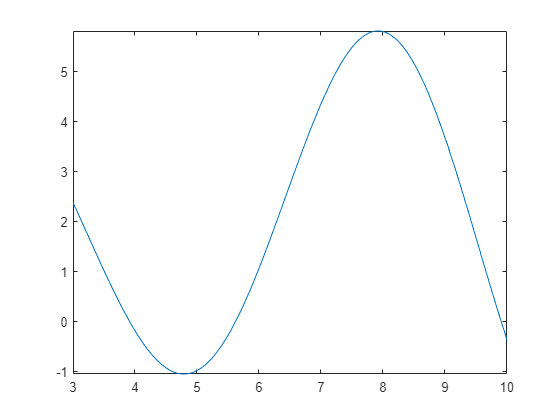

f = @(x) (x.*sin(x))./log(x) + 2;

fplot(f, [3,10])


xL = 3;
xu = 10;

bisect(f, xL, xu)

ans = 9.9061

Q8

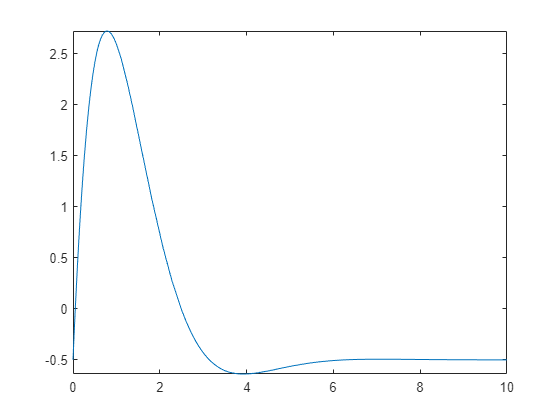

f = @(x) 10*sin(x).*exp(-x) - 1/2;

fplot(f, [0,10])

r0 = fzero(f, 0)

r0 = 0.0527

r1 = fzero(f, 3)

r1 = 2.4924

mean([r0, r1])

ans = 1.2726

Q9

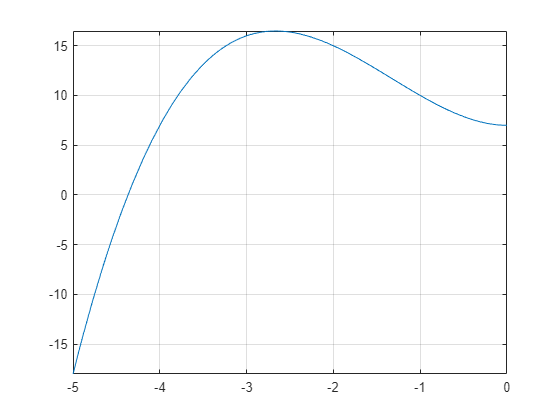

x = [-4];
f = @(x) x.^3 + 4*x.^2 + 7;
df = @(x) 3*x.^2 + 8*x;

fplot(f, [-5, 0])
grid on

for i = 1:3
    x(i+1) = x(i)- (f(x(i))/df(x(i)));
end

x

x =    -4.0000   -4.4375   -4.3690   -4.3670


Q11

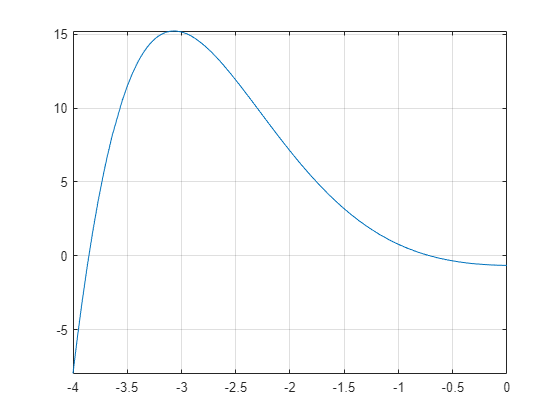

f = @(x) exp(-x).*cos(x-4);
fplot(f, [-4,0])
grid on

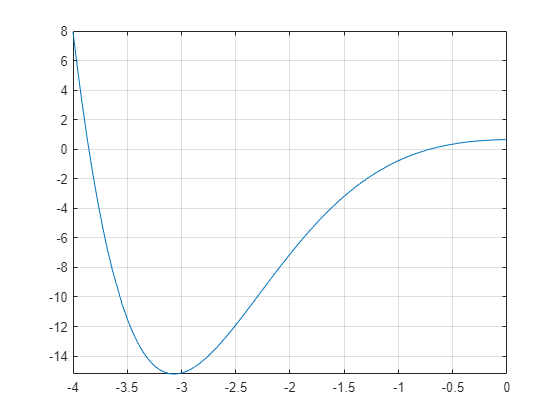

g = @(x) -f(x);
fplot(g, [-4,0])
grid on

[xCrit] = fminbnd(g, -4, 0)

xCrit = -3.0686

f(xCrit)

ans = 15.2109